# **Laboratorio 1**

**Experimentos**

%start enviroment
clear
clc

**    1.1. Hallar caracteristicas de la imagen**

I = imread('coins.png');

            Imagen a analizar

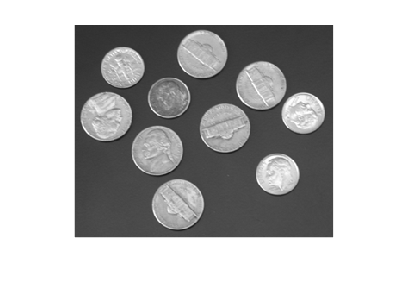

imshow(I)

            Obtenemos información de la imagen 

shapeI = whos; 

            Encontrar tamaño en bytes.

IBytes = shapeI.bytes;
fprintf('Tamaño en bytes: %i \n', IBytes)

Tamaño en bytes: 73800 


            Número de pixeles. 

IPixels = shapeI.size;
%fprintf('Distribución de pixeles: %d*%d', IPixels);
nPixels = IPixels(1,1)*IPixels(1,2);
fprintf('Número de pixeles: %i', nPixels);

Número de pixeles: 73800

            Número de bits por pixel.

bytesPorPixel = IBytes/nPixels;
bitsPorPixel = bytesPorPixel*(8/1);
fprintf('Número de bits por pixel: %i', bitsPorPixel);

Número de bits por pixel: 8

**    1.2. Comparar los tamaños de los archivos**

imwrite(I, 'coins.png');
imwrite(I, 'coins.jpg');
imwrite(I, 'coins5.jpg', 'quality', 5);

Ipng = imread('coins.png');
Ijpg = imread('coins.jpg');
Ijpg5 = imread('coins5.jpg');

whos Ipng

  Name        Size             Bytes  Class    Attributes

  Ipng      246x300            73800  uint8              



whos Ijpg

  Name        Size             Bytes  Class    Attributes

  Ijpg      246x300            73800  uint8              



whos Ijpg5

  Name         Size             Bytes  Class    Attributes

  Ijpg5      246x300            73800  uint8              



    2.1 

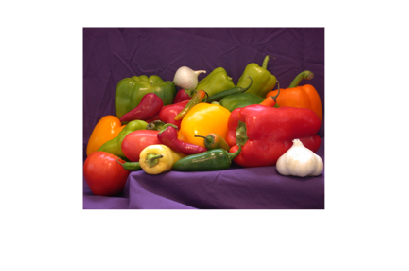


map =

     []



[I2, map] = imread('peppers_RGB_tiled.tif');
imshow(I2)